# 向下重采样

1.参数设置

clearvars
orgInv      = 0.01;                            %原采样间隔（每秒100点）
newInv      = 0.02;                            %新采样间隔（每秒50点）
orgDatLen   = 4096;                            %原数据点数
newDatLen   = floor(orgDatLen*orgInv/newInv);  %新数据点数
orgFs       = 1/orgInv;                        %原采样率
newFs       = 1/newInv;                        %新采样率
orgCutFre   = orgFs/2;                         %原截止频率=1/2采样率
ratio       = newInv/orgInv;                   %新采样间隔/原采样间隔
zeta        = newFs/(2*orgCutFre);             %重采样的低通滤波器参数


figure;
%--绘制采样率为1000和100的波形-------------------------------------------------
t1000=0:0.001:orgDatLen*orgInv-1;
mix1000=sin(2*pi*1*(t1000+1-orgInv))+0.5*sin(2*pi*30*(t1000+1-orgInv));
plot(t1000,mix1000,'g')
hold on

t100=(0:orgDatLen-1)/orgFs;
mix100=sin(2*pi*1*t100)+0.5*sin(2*pi*30*t100);
plot(t100(1+1:orgDatLen-orgFs),mix100(1+orgFs:orgDatLen-1),'r');
hold on


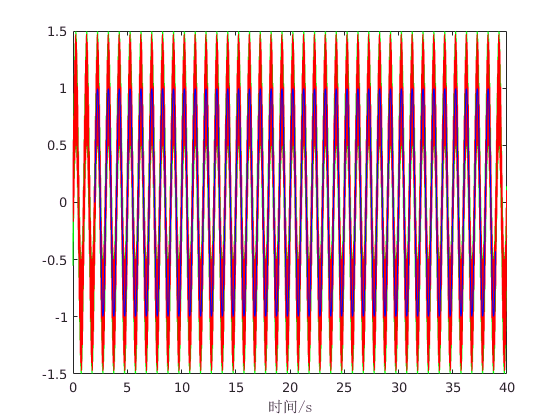

%--向下采样为50采样率---------------------------------------------------------
% Sinc是一个滤波器，它除去给定带宽之上的信号分量而只保留低频信号的理想电子滤波器。
% 理想的Sinc滤波器（矩形滤波器）,有无限的延迟，现实世界中的滤波器只能是它的一个近似。
comSta = floor(orgFs/ratio)+orgFs+1;
comEnd = newDatLen-floor(orgFs/ratio)-1;
difDat = zeros(1,comEnd);                     %初始化重采样序列
for m=comSta:comEnd
    for n=floor(m*ratio)-orgFs:1:floor(m*ratio)+orgFs
        difDat(m)=difDat(m)+zeta*mix100(n)*sinc(zeta*(m*ratio-n));
    end
end

t50=(0:newDatLen-1)/newFs;
%???为什么乘重采样的低通滤波器参数（zeta）???
%plot(tt1(floor(Fs0/ratio)+Fs0+1-Fs1+1:N1-floor(Fs0/ratio)-1-Fs1+1),x(floor(Fs0/ratio)+Fs0+1:N1-floor(Fs0/ratio)-1)*zeta,'b');
%hold on
plot(t50(orgFs+1:newDatLen-2*newFs),difDat(newFs+orgFs:newDatLen-newFs-1),'b');
hold on
xlabel('时间/s','FontName','SimSun')

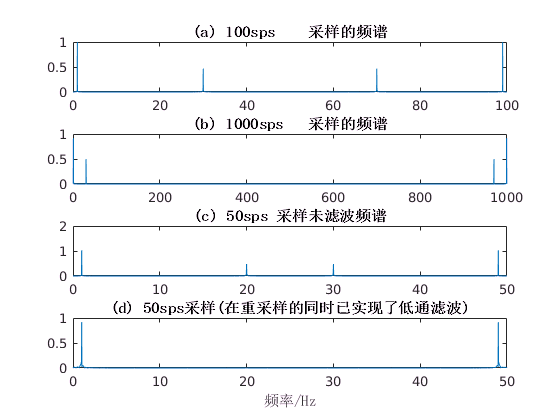

%--计算不同采样率波形频谱------------------------------------------------------
figure;
fft100=abs(fft(mix100,orgDatLen));
f=(0:(orgDatLen-1))*orgFs/orgDatLen;
subplot(4,1,1);
plot(f,fft100*2/orgDatLen);
title('(a) 100sps    采样的频谱','FontName','SimSun')

%???为什么使用32768（4096×8)???
fft1000=abs(fft(mix1000,32768));
fz=(0:(32768-1))/(32768*0.001);
subplot(4,1,2);
plot(fz,2*fft1000/32768);
title('(b) 1000sps   采样的频谱','FontName','SimSun');

Nx=length(difDat);
xn1=sin(2*pi*1*t50)+0.5*sin(2*pi*30*t50);
subplot(4,1,3);
fft50=abs(fft(xn1));
fxn1=((0:newDatLen-1))*newFs/newDatLen;
plot(fxn1,fft50*2/Nx);
title('(c) 50sps 采样未滤波频谱','FontName','SimSun');

subplot(4,1,4)
xfft=abs(fft(difDat));  
fx=(0:Nx-1)*newFs/Nx;
plot(fx,2*xfft/Nx);
title('(d) 50sps采样(在重采样的同时已实现了低通滤波)','FontName','SimSun');
xlabel('频率/Hz','FontName','SimSun');

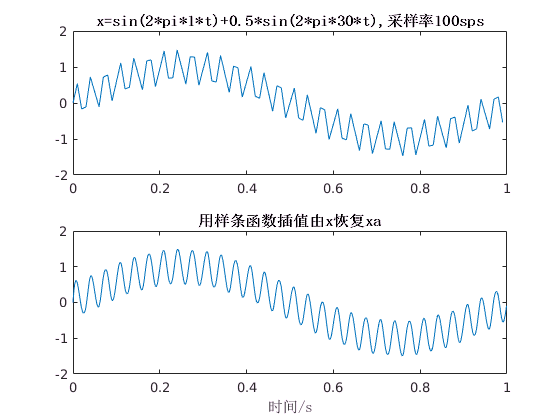

%--用样条函数（spline)模拟信号恢复----------------------------------------------
figure;
subplot(2,1,1)
plot(t100(1:100),mix100(1:100));
title('x=sin(2*pi*1*t)+0.5*sin(2*pi*30*t),采样率100sps','FontName','SimSun');

subplot(2,1,2)
ty1=0:0.001:orgDatLen*orgInv;
n=0:orgDatLen-1;
xa=spline(n*orgInv,mix100,ty1);
plot(ty1(1:1000),xa(1:1000))
title('用样条函数插值由x恢复xa','FontName','SimSun');
xlabel('时间/s','FontName','SimSun');